# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.6 特殊绘图

#### 2.6.16 棋盘格

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

要点：利用极坐标方式绘图

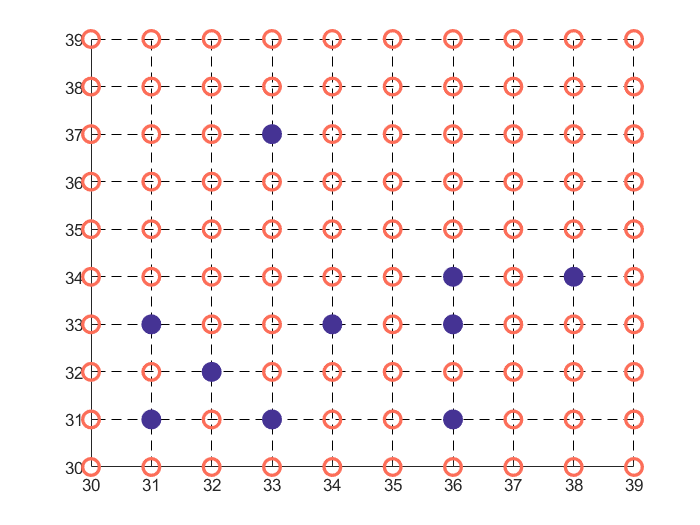

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors(); 
figure;
% 生成数据点
[x, y] = meshgrid(30:39);
x = x(:);
y = y(:);
scatter(x, y, 100, all_colors(1, :), 'LineWidth', 2);
hold on
% 随机填充几个点
number = 10;
index_x = randi(9, 1, number) + 30;
index_y = randi(9, 1, number) + 30;
scatter(index_x, index_y, 100, all_colors(6, :), 'MarkerFaceColor', all_colors(6, :), 'LineWidth', 2);
hold off
% 显示网格
grid on
% 网格属性
set(gca, 'GridAlpha', 1, 'GridColor', [0 0 0], 'GridLineStyle', '--');